# **Task 1: Deep Learning Modeling for Bearing Fault Diagnosis**

In this task, you will use Deep Learning Toolbox™ to create an AI model for diagnosing failure type of bearings, by loading data, training and evaluating a classification model.

## **1. Data Introduction: vibration data collected using sensors from rotating machinery **

Rotating machinery, such as gears, bearings, and motors, forms the backbone of many home appliances. In this task, we preprocessed the open source dataset: Machinery Failure Prevention Technology (MFPT) Challenge Data (Full dataset available at: [GitHub - mathworks/RollingElementBearingFaultDiagnosis-Data: Data set for Rolling Element Bearing Fault Diagnosis example in Predictive Maintenance Toolbox](https://github.com/mathworks/RollingElementBearingFaultDiagnosis-Data)), which contains 23 data sets collected from machines under various fault conditions. Localized faults in a rolling element bearing may occur in the outer race, the inner race, the cage, or a rolling element. High frequency resonances between the bearing and the response transducer are excited when the rolling elements strike a local fault on the outer or inner race, or a fault on a rolling element strikes the outer or inner race. The following picture shows a rolling element striking a local fault at the inner race. 

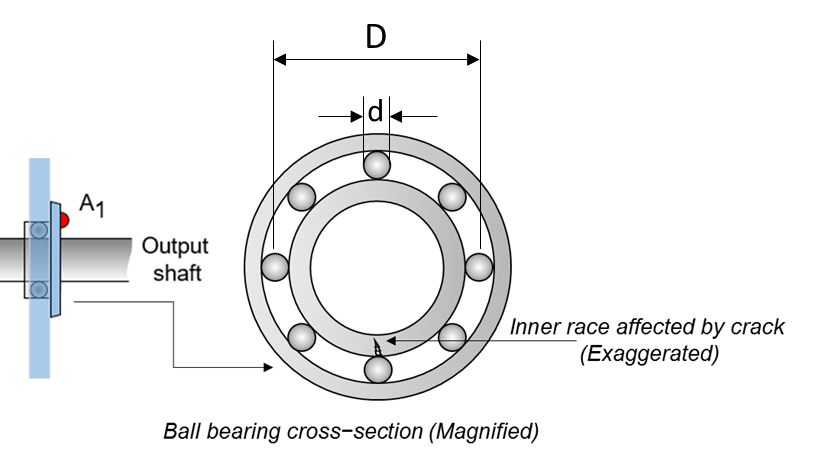

In task 1, 20 datasets were collected from a bearing test rig, with 3 under normal conditions, 3 with outer race faults under constant load, 7 with outer race faults under various loads, and 7 with inner race faults under various loads. The data in the stored tables are windowed as arrays of 5000 data points each.

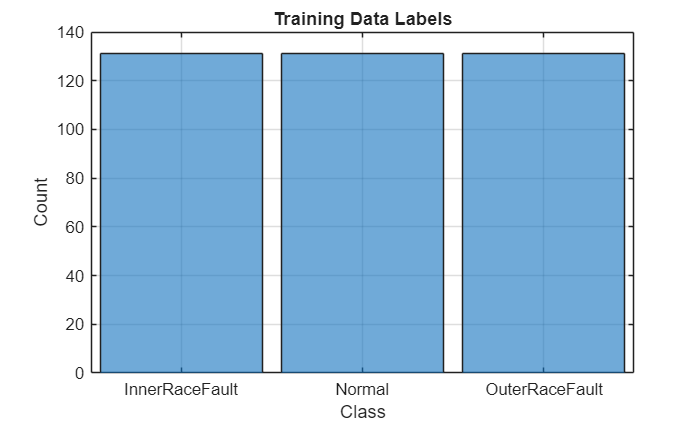

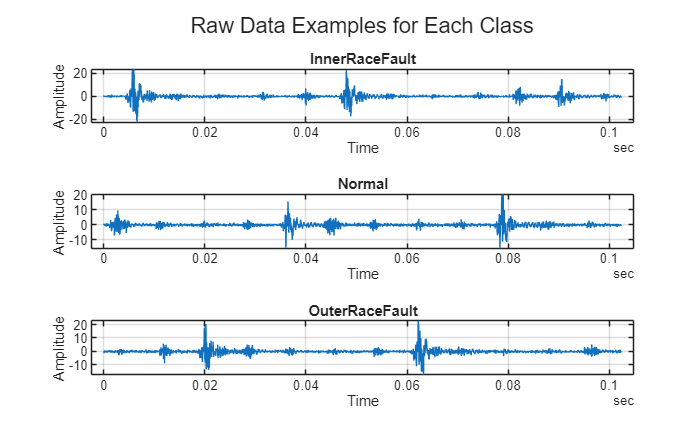

load("valTable.mat")
load("trainTable.mat")
load("testTable.mat")
plotRawData(trainTable)

## **2. Model Development: train a CNN model for bearing fault diagnosis **

In this exercise, you will train a convolutional neural network (CNN), a widely used deep learning model for fault diagnosis. Instead of using extracted features, we will use the raw data directly for model training, validation, and testing.

Prepare data from original dataset for training, validation and testing

% Prepare Data
allTrainData = cell2mat(trainTable{:,4});
muTrain = table2array(mean(allTrainData));
sigmaTrain = table2array(std(allTrainData));
% Get Training Data and Normalize
XTrain = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(trainTable(:,4)),'UniformOutput',false)');
XTest = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(testTable(:,4)),'UniformOutput',false)');
XVal = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(valTable(:,4)),'UniformOutput',false)');
YTrain = categorical(string(trainTable.label));
YTest = categorical(string(testTable.label));
YVal = categorical(string(valTable.label));
% Reshape the data to align with any hardware parsing requirement
XTrain = reshape(XTrain,[size(XTrain,1),1,size(XTrain,2)]);
XTest = reshape(XTest,[size(XTest,1),1,size(XTest,2)]);
XVal = reshape(XVal,[size(XVal,1),1,size(XVal,2)]);

You can use Deep Network Designer App to develop the structure of a neural network. In this exercise you will use the command line interface:

numClasses = numel(categories(YTrain));
minLength=5000;
net = dlnetwork([
    sequenceInputLayer(1,MinLength=minLength,Normalization="zerocenter")
    convolution1dLayer(256, 32, 'Padding','same','Name','conv1')
    reluLayer('Name','relu1')
    convolution1dLayer(16, 8, 'Padding','same','Name','conv2')
    reluLayer('Name','relu2')
    dropoutLayer(0.1)
    globalAveragePooling1dLayer
    fullyConnectedLayer(128,'Name','fc1')
    reluLayer('Name','relu3')
    fullyConnectedLayer(numClasses,'Name','fc2')
    softmaxLayer('Name','softmax')
]);

Next you can set training options and train the CNN network with training data. The training process is validated with the validation data.

miniBatchSize=32;
validationFrequency = floor(size(XTrain,3)/miniBatchSize);
if canUseGPU
    trainOn = "gpu";
else
    trainOn = "cpu";
end
options = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=20, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    ValidationData={XVal,YVal}, ...
    ValidationFrequency=validationFrequency, ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss", ...
    ExecutionEnvironment=trainOn);

Once the network structure is defined and training options are set, you can execute the code below to train the model. Note if GPU is available on the host machine, the training will be performed in GPU. Check how long it takes to finish the training.

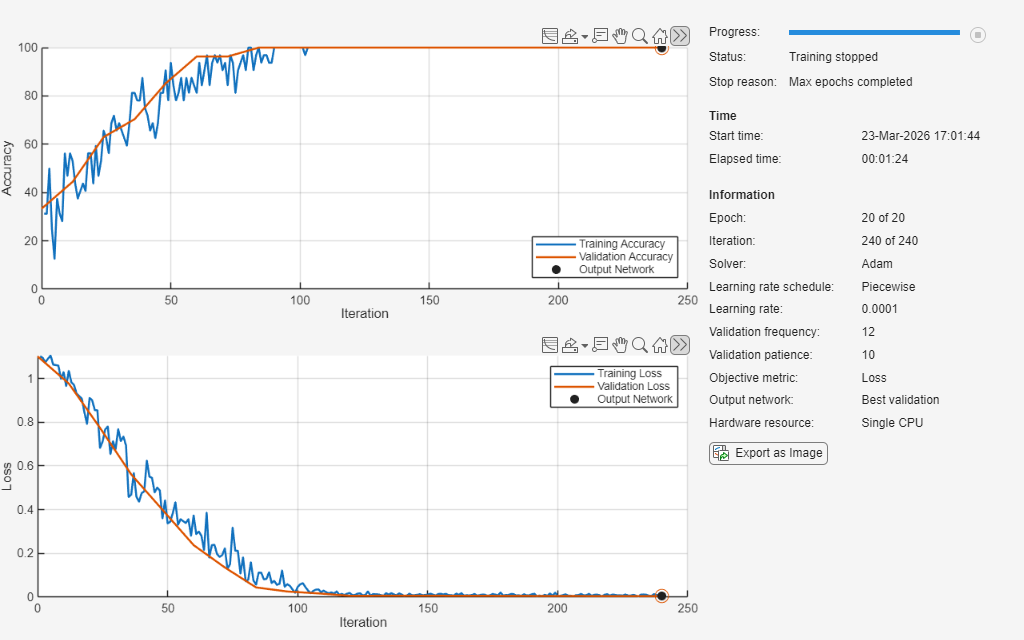

tic
net = trainnet(XTrain,YTrain,net,"crossentropy",options);

toc

Elapsed time is 84.865486 seconds.


Save the model as a MAT file for future use.

save('original_net.mat','net');

## **3. Model Evaluation: test the CNN model with new data**

Once the model has been trained and validated, you can evaluate its performance on the testing dataset. 

YPredOriginal = scores2label(minibatchpredict(net, XTest),unique(YTrain));
accuracy = sum(YPredOriginal == YTest)/numel(YTest)

accuracy = 1

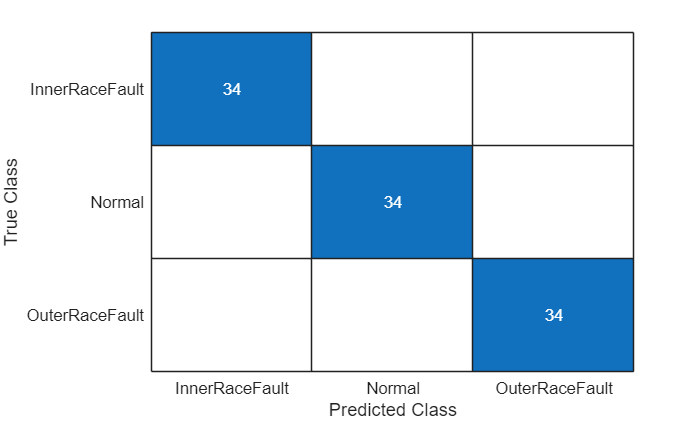

figure
confusionchart(YTest,YPredOriginal)

**Helper Function**

function plotRawData(originalData)
labels = string(originalData.label); % Directly access the Label column
unqiqueLabels = unique(labels);
figure;
histogram(categorical(labels, unique(labels)), 'DisplayOrder', 'ascend');
xlabel('Class',Interpreter='none');
ylabel('Count',Interpreter='none');
title('Training Data Labels',Interpreter='none');
grid on;

figure('Name','Raw Data ');tiledlayout(3,1)
numClasses = numel(unqiqueLabels);
for c = 1:numClasses
    nexttile
    TT = originalData.data{c};
    plot(TT.Time,TT.gs);
    xlabel('Time');
    ylabel('Amplitude');
    title(unqiqueLabels(c), 'Interpreter','none');
    grid on;
end
sgtitle('Raw Data Examples for Each Class');
end

